# Analysis of Evoked Fields

load CIBA120_data.mat
load grad_loc.mat

% gradiometer IDs
inputNames

inputNames = 1x204 cell array
    {'0112'}    {'0113'}    {'0122'}    {'0123'}    {'0132'}    {'0133'}    {'0142'}    {'0143'}    {'0212'}    {'0213'}    {'0222'}    {'0223'}    {'0232'}    {'0233'}    {'0242'}    {'0243'}    {'0312'}    {'0313'}    {'0322'}    {'0323'}    {'0332'}    {'0333'}    {'0342'}    {'0343'}    {'0412'}    {'0413'}    {'0422'}    {'0423'}    {'0432'}    {'0433'}    {'0442'}    {'0443'}    {'0512'}    {'0513'}    {'0522'}    {'0523'}    {'0532'}    {'0533'}    {'0542'}    {'0543'}    {'0612'}    {'0613'}    {'0622'}    {'0623'}    {'0632'}    {'0633'}    {'0642'}    {'0643'}    {'0712'}    {'0713'}    {'0722'}    {'0723'}    {'0732'}    {'0733'}    {'0742'}    {'0743'}    {'0812'}    {'0813'}    {'0822'}    {'0823'}    {'0912'}    {'0913'}    {'0922'}    {'0923'}    {'0932'}    {'0933'}    {'0942'}    {'0943'}    {'1012'}    {'1013'}    {'1022'}    {'1023'}    {'1032'}    {'1033'}    {'1042'}    {'1043'}    {'1112'}    {'1113'}    {'1122'}    {'1123'}    {'1132


% time from word onset (ms)
time_points

time_points =   -167  -166  -165  -164  -163  -162  -161  -160  -159  -158  -157  -156  -155  -154  -153  -152  -151  -150  -149  -148  -147  -146  -145  -144  -143  -142  -141  -140  -139  -138  -137  -136  -135  -134  -133  -132  -131  -130  -129  -128  -127  -126  -125  -124  -123  -122  -121  -120  -119  -118



% congruent condition (epochs x channels x timepoints)
size(ep_cong_s1)

ans =          108         204        1001



% size(ep_incong_s1)
% size(ep_cong_s2)
% size(ep_incong_s2)

global_cong_s1 = squeeze(mean(ep_cong_s1));
global_incong_s1 = squeeze(mean(ep_incong_s1));

mean_cong_s1 = squeeze(mean(global_cong_s1));
mean_incong_s1 = squeeze(mean(global_incong_s1));

std_cong_s1 = squeeze(std(global_cong_s1));
std_incong_s1 = squeeze(std(global_incong_s1));

global_cong_s2 = squeeze(mean(ep_cong_s2));
global_incong_s2 = squeeze(mean(ep_incong_s2));

mean_cong_s2 = squeeze(mean(global_cong_s2));
mean_incong_s2 = squeeze(mean(global_incong_s2));

std_cong_s2 = squeeze(std(global_cong_s2));
std_incong_s2 = squeeze(std(global_incong_s2));

function p = plotResponse(x, y, yerr, col, text)

    gray = [.7 .7 .7];
    y_ticks = [-5 * 10^-12, -2.5 * 10^-12, 0, 2.5 * 10^-12, 5 * 10^-12];
    y_lims = y_ticks([1, end]);

    errorbar(x, y, yerr, "Color", gray, "LineWidth", 0.1, "MarkerSize", 0.1, "CapSize", 0)
    hold on
    
    plot(x, y, col)
    xline(0, "--k")
    
    ylim(y_lims)
    yticks(y_ticks)
    
    xlabel("Time in ms")
    ylabel("Signal Amplitude")
    
    title(text)
    hold off

end

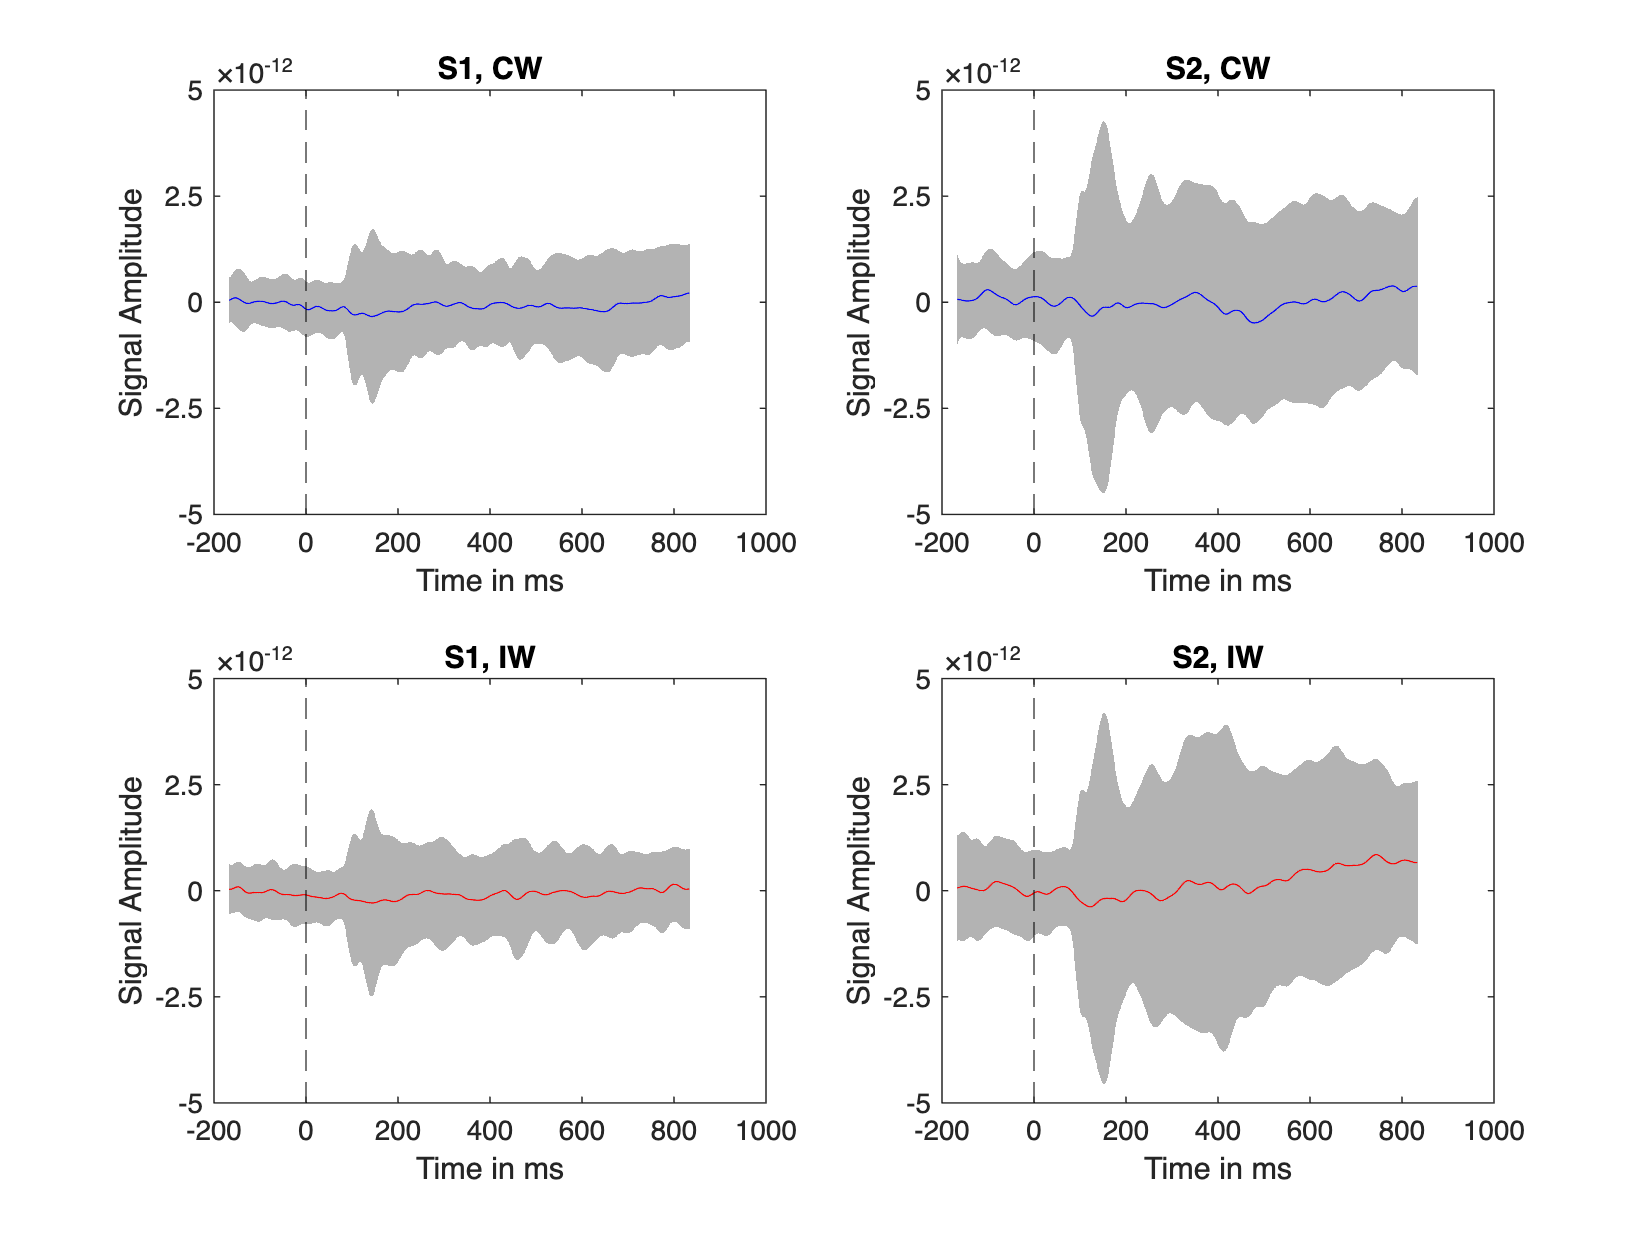

figure;

subplot(2, 2, 1)
plotResponse(time_points, mean_cong_s1, std_cong_s1, "b", "S1, CW")

subplot(2, 2, 2)
plotResponse(time_points, mean_cong_s2, std_cong_s2, "b", "S2, CW")

subplot(2, 2, 3)
plotResponse(time_points, mean_incong_s1, std_incong_s1, "r", "S1, IW")

subplot(2, 2, 4)
plotResponse(time_points, mean_incong_s2, std_incong_s2, "r", "S2, IW")